# Plotting surfaces

## Introduction

Plotting graphs is indispensable in science and engineering as a tool for communicating information and results. MATLAB provides an extensive set of commands that facilitate the creation of high-quality plots. 

In this activity we will explore the basic commands to create and manipulate surface plots.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

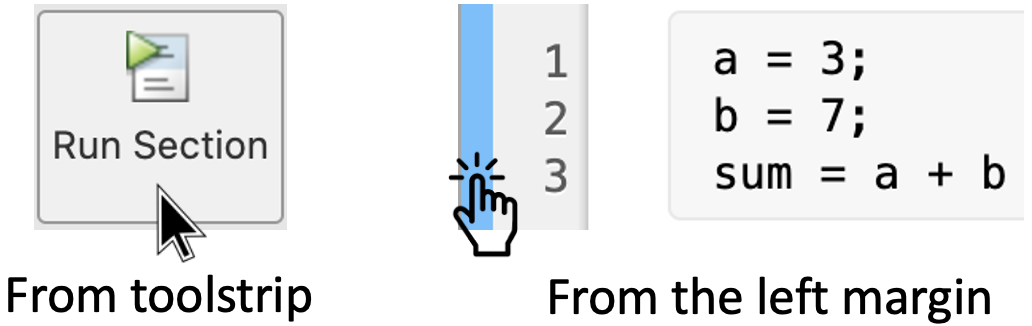

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Grids and Surfaces

Let $f(x,y)=x^2-y^2$, a function of two variables, with domain given by the region $1\le x\le 4$, $1\le y\le 4$ in the xy-plane.

To plot this surface first compute $z=f(x,y)$ for many points $(x,y)\in [1,4]\times [1,4]$, plot those points $(x,y,z)$ in 3D, then join them up to make it look like a surface.

In MATLAB, this is easy. First, we have to make grids of the $x$ and $y$ values where we want to calculate the values of $f(x,y)$. In MATLAB we can do this using the command:

The [`meshgrid`](https://au.mathworks.com/help/matlab/ref/meshgrid.html#d123e919673) command takes the vector (1,2,3,4) and produces two matrices called `X` and `Y` whose values correspond to the integer valued x and y coordinates of the domain, that is, $1\le x\le 4$,$1\le y\le 4$ of $f(x,y)$.

Now, we can produce a new matrix called `Z` that holds the $f(x,y)$ values at each point of the integer grid as follows:

**Remark:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

Now we can produce a plot of the surface using the command [surf](https://au.mathworks.com/help/matlab/ref/surf.html):

To see how this works, run this section.

[X, Y] = meshgrid(1:4);
Z = X.^2- Y.^2;
surf(X,Y,Z)

The first thing you may notice is that the surface is not smooth. To create a smoother version just replace `1:4 `by `1:0.25:4,` in the previous code. Re-run the section to appreciate the result. Learn more about the colon operator here: [colon operator](https://au.mathworks.com/help/matlab/ref/colon.html).

## 2. Plot settings

### 2.1 Specify `colormap` colours for a surface plot

In MATLAB we can specify the colours for a surface plot by including a fourth matrix input, `C`. The surface plot uses `Z` for height and `C` for colour. 

Specify the colours using a `colormap`, which uses single numbers to stand for colours on a spectrum. When you use a `colormap`, `C` is the same size as `Z`. Add a colour bar to the graph to show how the data values in `C` correspond to the colours in the colormap.

For example, consider the function $f(x,y)=x\exp\left(-x^2-y^2\right)$ on the region $-2\le x\le 2$, $-2\le y\le 2$.  

To include the `colormap` to this surface we use the following code. Run this section to see the output:

[X,Y] = meshgrid(-2:0.2:2);
Z = X.*exp(-X.^2-Y.^2);
C = Z;
surf(X,Y,Z,C)
colorbar

### 2.2 **Modify Surface Plot Appearance**

In MATLAB we can create a semitransparent surface by specifying the `FaceAlpha` name-value pair with `0.5` as the value. To allow further modifications, assign the surface object to the variable `s`.

For example:

[X,Y] = meshgrid(-5:.5:5);
Z = Y.*sin(X) - X.*cos(Y);
s = surf(X,Y,Z,'FaceAlpha',0.5)


Use the variable `s` to access and modify properties of the surface object after it is created. For example, hide the edges by setting the `EdgeColor` property. To do this just add the following line

`s.EdgeColor = ``'none'``;`

at the end of the previous code. Re-run this section to see the output.

**Note:** There are a wide variety of properties that can be modified. For more details see: [Surface properties](https://au.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.surface-properties.html).

## 3. Hands on practice

#### Activity 1:

Plot the following surfaces in the indicated region.

- $f(x,y)=\sin(x-y) - \cos(x+y)$ for $x\in [-4,4]$ and $y\in[-4,4]$.

- $g(x,y)=\sin\left(x^2 + y^2\right) / \left(x^2 + y^2\right)$ for $x\in [-5,5]$ and $y\in[-5,5]$.

Write your code here:

% Plot f(x,y)



% Plot g(x,y)




#### Activity 2:

Define two new X,Y grids using the code:

Plot the function


$$h(x,y)=80y^2\exp\left(-x^{2}-0.3y^{2}\right)$$


over the grids given by (X1,Y1) and (X2,Y2). 

Write your code here:

What do you notice? What do you wonder? Write in the code above, as comment, at least two differences you notice about the two surface plots.